# Synthetic Data FacTBREK experiments

addpath('../tproduct toolbox 2.0 (transform)/')
warning('off','all')

%To-do: implement trial averaging, try different inner block sizes, do
%experiment for all other combinations of system sizes

First, we'll generate a tensor linear system.

%fixed:
p = 7;
n = 5;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_2 = 10;

%V underdetermined (m_1 > m_2), A overdetermined (m >= 20)--Works
%m = 20;
%m = 30;
m = 40;
m_1 = 5;
%m_1 = m_2;

%V underdetermined (m_1 > m_2), A underdetermined (m < 20)--Doesn't Works
%m = 10;
%m = 15;%
%m_1 = 5;

%V overdetermined (m_1 < m_2), A overdetermined (m > 20)--Doesn't work
% m = 20;
% m = 30;
%m = 40;
%m_1 = 12;

%generate tensors
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
%V = teye(m_2,p);
A=tprod(U,V); 

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B_true = tprod(U, Z_ddagg);

B = B_true + 0.0001*Y_perp;


%generate equivalent matrix system
[matU,matV, matB,matX_true] = matricization_factorized(U,V,B,X_true);

Now, we run FacTBRK with a variety of choices of outer block sizes on this inconsistent system.

X_0 = randn(size(X_true));
X_LN = tprod(tpinv(V),Z_ddagg);
%norm(X_LN(:)-X_true(:))
num_its = 2000; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 1; %remember that the updates only make sense for block size <= number of columns

errs = zeros(size(out_block_sizes,2),num_its+1);
res_errs = zeros(size(out_block_sizes,2),num_its+1);
ln_errs = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs = zeros(size(out_block_sizes,2),num_its+1);
norms = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs(i,:),res_errs(i,:),ln_errs(i,:),res_ln_errs(i,:),norms(i,:)] = facTBRK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

max(max(max(X - X_LN)))

ans = 5.1391e-04

Let's plot the errors.

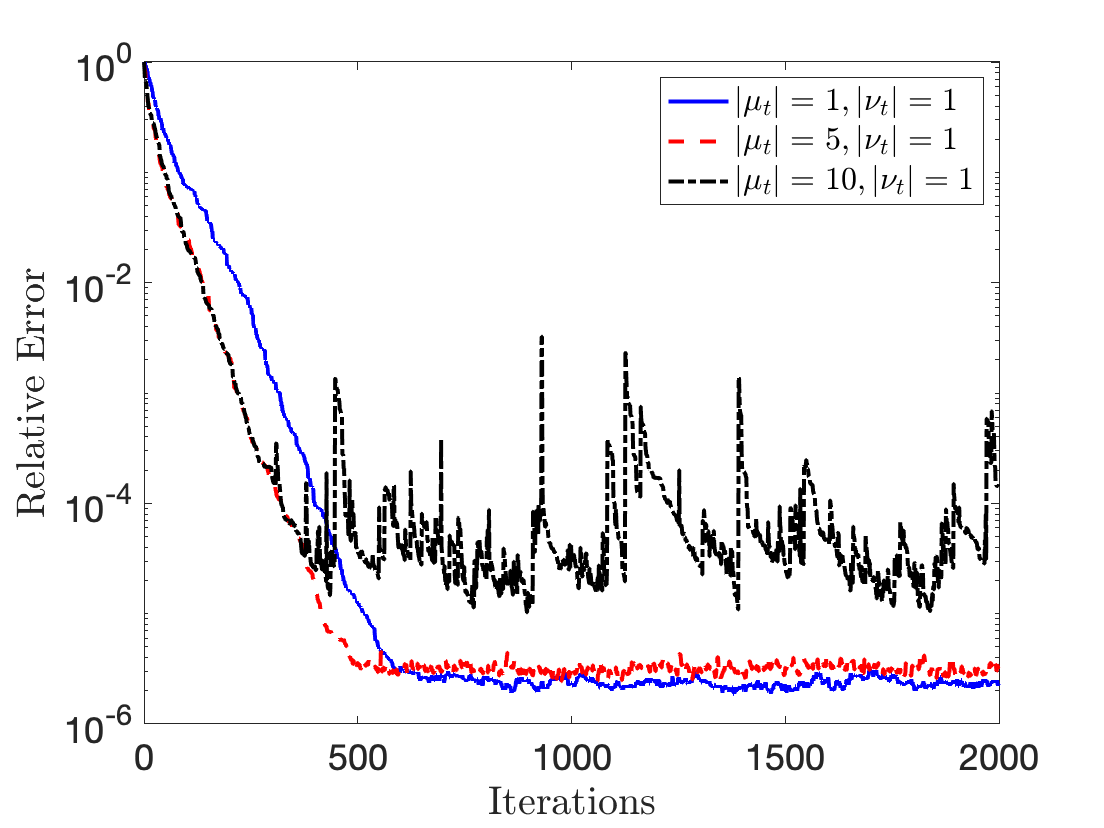

%plot errors vs iterations
clc
figure(1);
%hold on
line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ln_errs(1,:),line_styles{1},0:num_its,ln_errs(2,:),line_styles{2},0:num_its,ln_errs(3,:),line_styles{3},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
%legendStrings = "block size = " + string(out_block_sizes);
legend('$|\mu_t| = 1, |\nu_t| = 1$','$|\mu_t| = 5, |\nu_t| = 1$', '$|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex')
%hold off

saveas(gca,"figs/inconsistent_facTBRK.png");

saveas(gca,"figs/inconsistent_facTBRK",'fig');

Now, we run FacTBREK with a variety of choices of outer block sizes on this inconsistent system.

X_0 = randn(size(X_true));
X_LN2 = tprod(tpinv(A),B);
X_LN = tprod(tpinv(V),Z_ddagg);
norm(X_LN(:)-X_LN2(:))

ans = 2.6494e-14

num_its = 2000; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 1; %remember that the updates only make sense for block size <= number of columns

errs_e = zeros(size(out_block_sizes,2),num_its+1);
res_errs_e = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_e = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_e = zeros(size(out_block_sizes,2),num_its+1);
norms_e = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_e(i,:),res_errs_e(i,:),ln_errs_e(i,:),res_ln_errs_e(i,:),norms_e(i,:)] = facTBREK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

max(max(max(X - X_LN)))

ans = 2.2649e-14

Let's plot the errors.

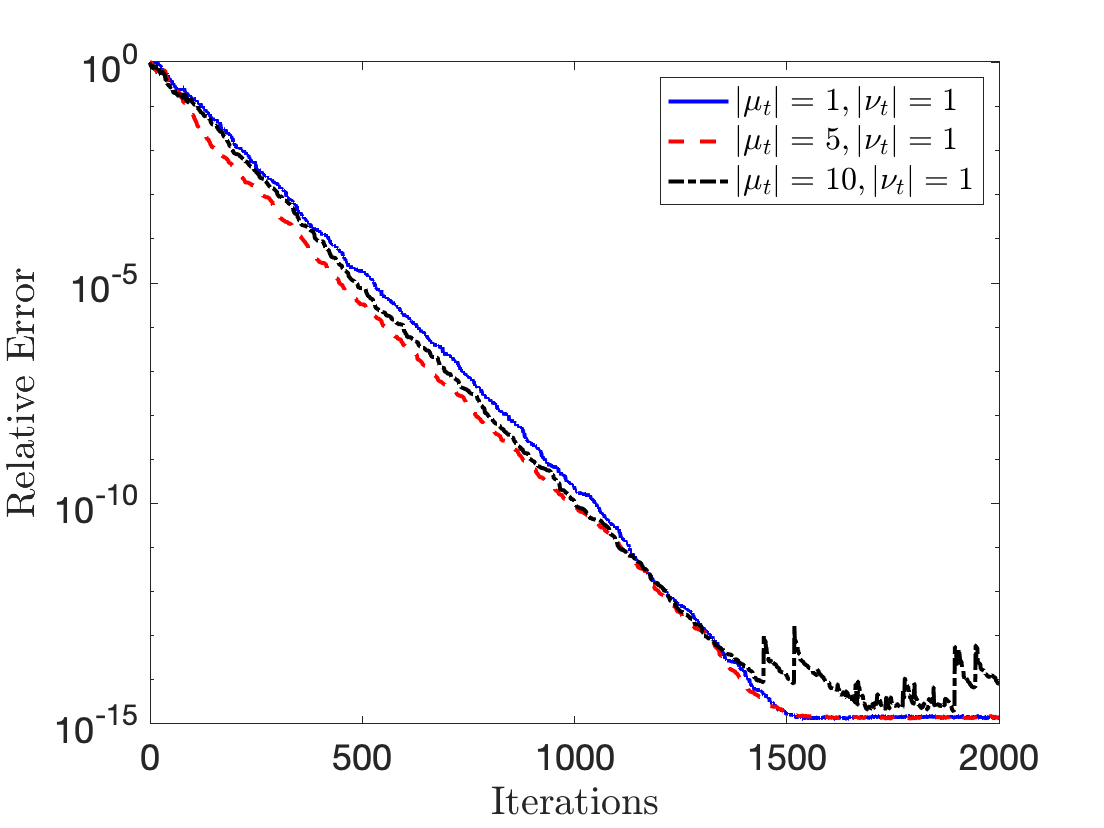

%plot errors vs iterations
clc
figure(2);
%hold on
line_styles = {'b-','r--','k-.','c:','g-*'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,ln_errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:num_its,ln_errs_e(1,:),line_styles{1},0:num_its,ln_errs_e(2,:),line_styles{2},0:num_its,ln_errs_e(3,:),line_styles{3},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
legendStrings = "block size = " + string(out_block_sizes);
legend('$|\mu_t| = 1, |\nu_t| = 1$','$|\mu_t| = 5, |\nu_t| = 1$', '$|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex')
%hold off

saveas(gca,"figs/inconsistent_facTBREK.png");

saveas(gca,"figs/inconsistent_facTBREK",'fig');

Now, we plot these results on the same plot.

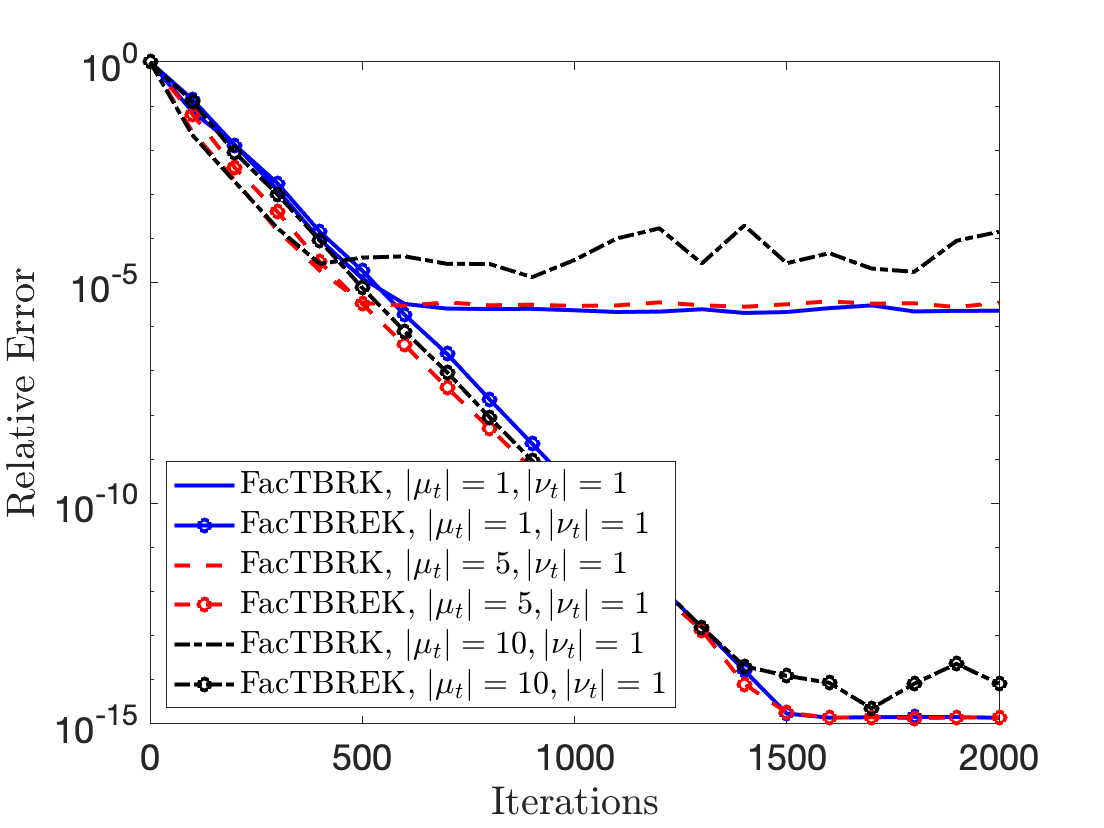

clc
figure(2);
%hold on
line_styles = {'b-','b-o','r--','r--o','k-.','k-.o'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,ln_errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:100:num_its,ln_errs(1,1:100:num_its+1),line_styles{1},0:100:num_its,ln_errs_e(1,1:100:num_its+1),line_styles{2},0:100:num_its,ln_errs(2,1:100:num_its+1),line_styles{3},0:100:num_its,ln_errs_e(2,1:100:num_its+1),line_styles{4},0:100:num_its,ln_errs(3,1:100:num_its+1),line_styles{5},0:100:num_its,ln_errs_e(3,1:100:num_its+1),line_styles{6},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
%legendStrings = "block size = " + string(out_block_sizes);
legend('FacTBRK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBRK, $|\mu_t| = 5, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 5, |\nu_t| = 1$', 'FacTBRK, $|\mu_t| = 10, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex','Location','southwest')

saveas(gca,"figs/inconsistent_facTBRKandfacTBREK.png");

saveas(gca,"figs/inconsistent_facTBRKandfacTBREK",'fig');

#### FacTBREK on consistent and inconsistent system

Now that we have the sanity check experiments out of the way, let's see how FacTBREK behaves on a consistent and inconsistent system.

%generate systems
p = 7;
n = 5;
m_2 = 10;
m = 40;
m_1 = 5;

%generate tensors
U = randn(m, m_2,p);
V = randn(m_2,m_1,p); 

X_true = randn(m_1,n,p);
Z_ddagg = tprod(V,X_true);

%generate component in col(U)^perp
Y_tild = randn(m,n,p);
X_tild = tprod(tpinv(U),Y_tild);
Y_perp = Y_tild - tprod(U,X_tild);

%generate consistent measurements
B_true = tprod(U, Z_ddagg);
B = B_true + 0.0001*Y_perp;

Now we run FacTBREK on the systems defined by B and B_true.

X_0 = randn(size(X_true));
X_LN2 = tprod(tpinv(A),B);
X_LN = tprod(tpinv(V),Z_ddagg);
norm(X_LN(:)-X_LN2(:))

ans = 16.3349

num_its = 2000; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 1; %remember that the updates only make sense for block size <= number of columns

errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_errs_con = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
norms_con = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_con(i,:),res_errs_con(i,:),ln_errs_con(i,:),res_ln_errs_con(i,:),norms_con(i,:)] = facTBREK_err(U,V,B_true,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
norms_incon = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_incon(i,:),res_errs_incon(i,:),ln_errs_incon(i,:),res_ln_errs_incon(i,:),norms_incon(i,:)] = facTBREK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

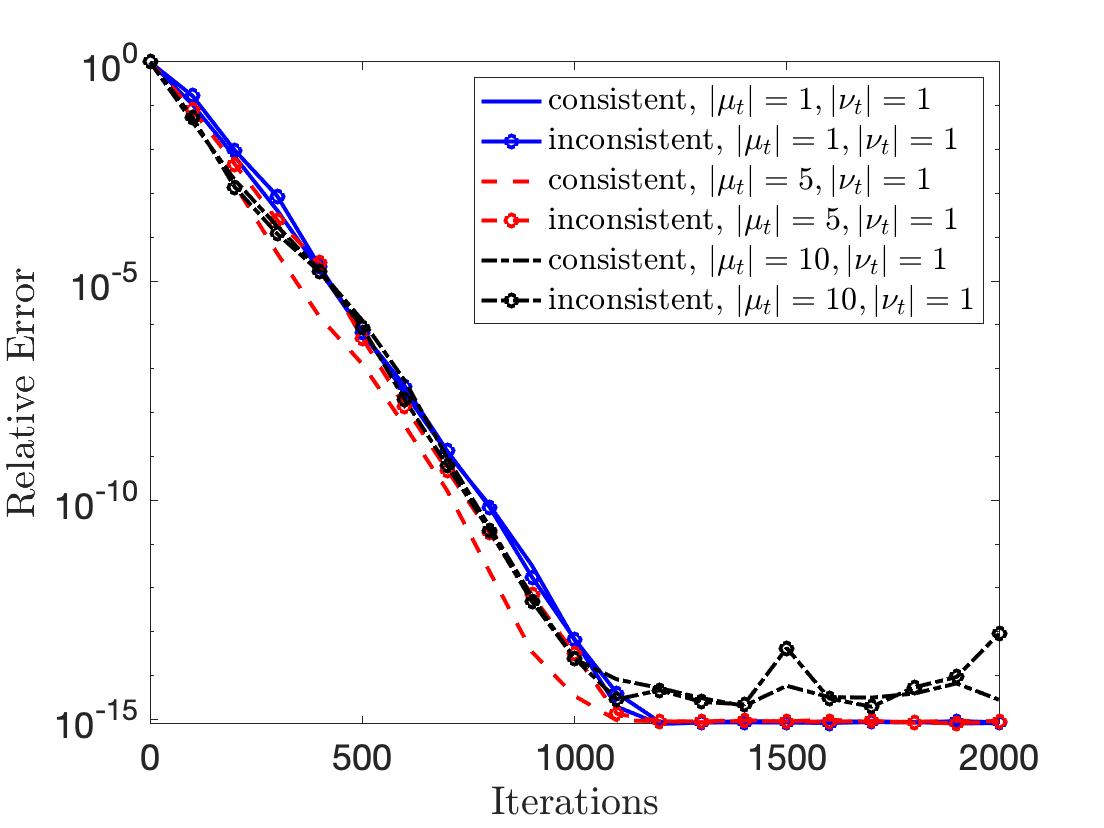

clc
figure(2);
%hold on
line_styles = {'b-','b-o','r--','r--o','k-.','k-.o'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,ln_errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:100:num_its,ln_errs_con(1,1:100:num_its+1),line_styles{1},0:100:num_its,ln_errs_incon(1,1:100:num_its+1),line_styles{2},0:100:num_its,ln_errs_con(2,1:100:num_its+1),line_styles{3},0:100:num_its,ln_errs_incon(2,1:100:num_its+1),line_styles{4},0:100:num_its,ln_errs_con(3,1:100:num_its+1),line_styles{5},0:100:num_its,ln_errs_incon(3,1:100:num_its+1),line_styles{6},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
%legendStrings = "block size = " + string(out_block_sizes);
legend('consistent, $|\mu_t| = 1, |\nu_t| = 1$','inconsistent, $|\mu_t| = 1, |\nu_t| = 1$','consistent, $|\mu_t| = 5, |\nu_t| = 1$','inconsistent, $|\mu_t| = 5, |\nu_t| = 1$', 'consistent, $|\mu_t| = 10, |\nu_t| = 1$','inconsistent, $|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex')

saveas(gca,"figs/consistentandinconsistent_facTBREK.png");

saveas(gca,"figs/consistentandinconsistent_facTBREK",'fig');

#### FacTBRK on consistent and FacTBREK on inconsistent system

X_0 = randn(size(X_true));
X_LN2 = tprod(tpinv(A),B);
X_LN = tprod(tpinv(V),Z_ddagg);
norm(X_LN(:)-X_LN2(:))

ans = 16.3349

num_its = 2000; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 1; %remember that the updates only make sense for block size <= number of columns

errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_errs_con = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
norms_con = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_con(i,:),res_errs_con(i,:),ln_errs_con(i,:),res_ln_errs_con(i,:),norms_con(i,:)] = facTBRK_err(U,V,B_true,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
norms_incon = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_incon(i,:),res_errs_incon(i,:),ln_errs_incon(i,:),res_ln_errs_incon(i,:),norms_incon(i,:)] = facTBREK_err(U,V,B,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

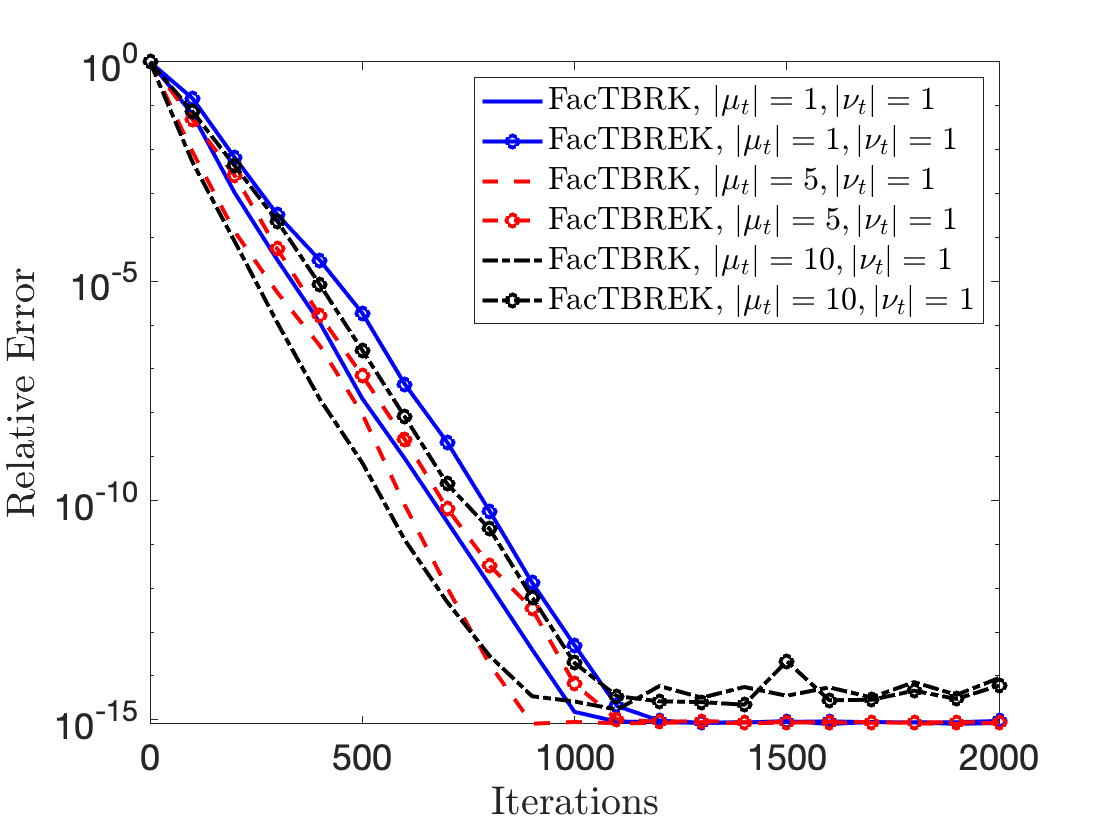

clc
figure(2);
%hold on
line_styles = {'b-','b-o','r--','r--o','k-.','k-.o'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,ln_errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:100:num_its,ln_errs_con(1,1:100:num_its+1),line_styles{1},0:100:num_its,ln_errs_incon(1,1:100:num_its+1),line_styles{2},0:100:num_its,ln_errs_con(2,1:100:num_its+1),line_styles{3},0:100:num_its,ln_errs_incon(2,1:100:num_its+1),line_styles{4},0:100:num_its,ln_errs_con(3,1:100:num_its+1),line_styles{5},0:100:num_its,ln_errs_incon(3,1:100:num_its+1),line_styles{6},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
%legendStrings = "block size = " + string(out_block_sizes);
legend('FacTBRK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBRK, $|\mu_t| = 5, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 5, |\nu_t| = 1$', 'FacTBRK, $|\mu_t| = 10, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex')

saveas(gca,"figs/consistent_facTBRK_and_inconsistent_facTBREK.png");

saveas(gca,"figs/consistent_facTBRK_and_inconsistent_facTBREK",'fig');

#### FacTBRK and FacTBREK on consistent system

X_0 = randn(size(X_true));
X_LN2 = tprod(tpinv(A),B);
X_LN = tprod(tpinv(V),Z_ddagg);
norm(X_LN(:)-X_LN2(:))

ans = 16.3349

num_its = 2000; %num iterations
out_block_sizes = [1,5,10]; %remember that the updates only make sense for block size <= number of columns
in_block_size = 1; %remember that the updates only make sense for block size <= number of columns

errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_errs_con = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_con = zeros(size(out_block_sizes,2),num_its+1);
norms_con = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_con(i,:),res_errs_con(i,:),ln_errs_con(i,:),res_ln_errs_con(i,:),norms_con(i,:)] = facTBRK_err(U,V,B_true,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
res_ln_errs_incon = zeros(size(out_block_sizes,2),num_its+1);
norms_incon = zeros(size(out_block_sizes,2),num_its+1);

for i=1:size(out_block_sizes,2)
    out_block_size = out_block_sizes(i);
    [X,errs_incon(i,:),res_errs_incon(i,:),ln_errs_incon(i,:),res_ln_errs_incon(i,:),norms_incon(i,:)] = facTBREK_err(U,V,B_true,X_0,X_true,X_LN,num_its,out_block_size,in_block_size);
end

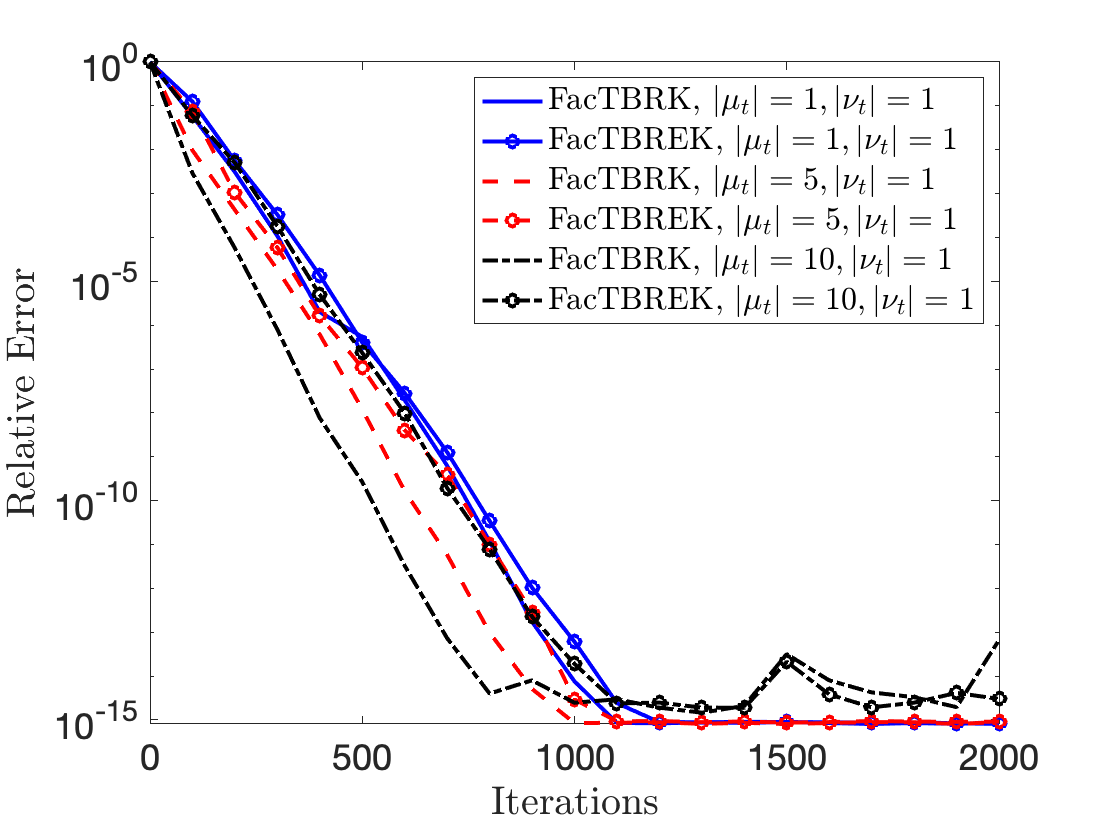

clc
figure(2);
%hold on
line_styles = {'b-','b-o','r--','r--o','k-.','k-.o'};
% for i = 1:size(out_block_sizes,2)
%     i
%     semilogy(0:num_its,ln_errs(i,:),line_styles{i},'LineWidth',2)
% end
semilogy(0:100:num_its,ln_errs_con(1,1:100:num_its+1),line_styles{1},0:100:num_its,ln_errs_incon(1,1:100:num_its+1),line_styles{2},0:100:num_its,ln_errs_con(2,1:100:num_its+1),line_styles{3},0:100:num_its,ln_errs_incon(2,1:100:num_its+1),line_styles{4},0:100:num_its,ln_errs_con(3,1:100:num_its+1),line_styles{5},0:100:num_its,ln_errs_incon(3,1:100:num_its+1),line_styles{6},'LineWidth',2)
set(gca,'FontSize',18)
xlabel('Iterations','Interpreter','latex','FontSize',20) 
ylabel('Relative Error','Interpreter','latex','FontSize',20)%ylim([0,1.2])
%legendStrings = "block size = " + string(out_block_sizes);
legend('FacTBRK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 1, |\nu_t| = 1$','FacTBRK, $|\mu_t| = 5, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 5, |\nu_t| = 1$', 'FacTBRK, $|\mu_t| = 10, |\nu_t| = 1$','FacTBREK, $|\mu_t| = 10, |\nu_t| = 1$','Interpreter','latex')

saveas(gca,"figs/consistent_facTBRKandfacTBREK.png");

saveas(gca,"figs/consistent_facTBRKandfacTBREK",'fig');